Simple Fixed-Point Iteration Convergence

Newton-Raphson Method

close;clear;clc

syms function_x x
function_x(x) = exp(-x)-x

$$function\_x(x) = {\mathrm{e}}^{-x}-x$$

xp = 0:0.1:2;

xp =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


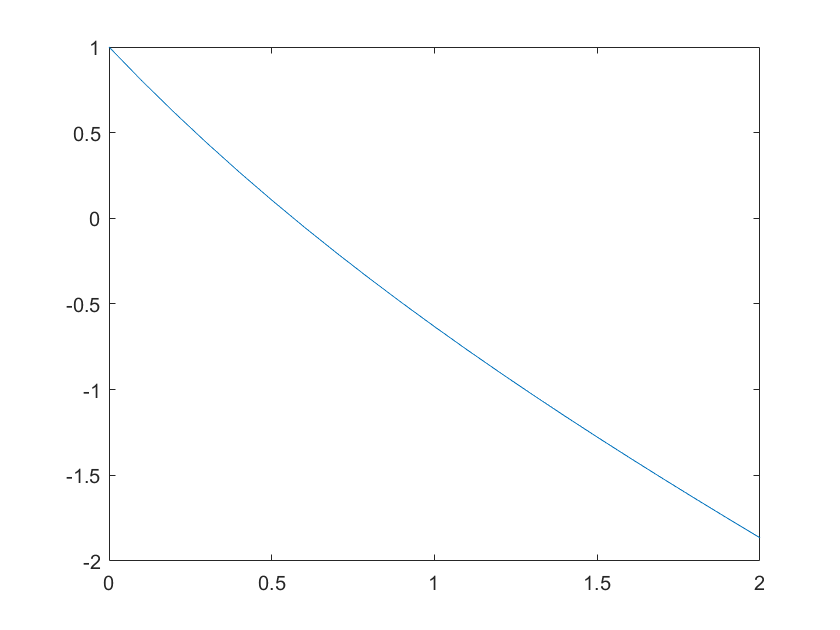

plot(xp,function_x(xp))


x_i = 0;

function_x_order1 = diff(function_x)

$$function\_x\_order1(x) = -{\mathrm{e}}^{-x}-1$$

x_i_forward = x_i - (function_x(x_i)/function_x_order1(x_i))

$$x\_i\_forward = \frac{1}{2}$$

clear;close;clc

syms function_x x

function_x(x) = 2*sin(x) - (x^2/10)

$$function\_x(x) = 2\,\sin\left(x\right)-\frac{x^{2}}{10}$$

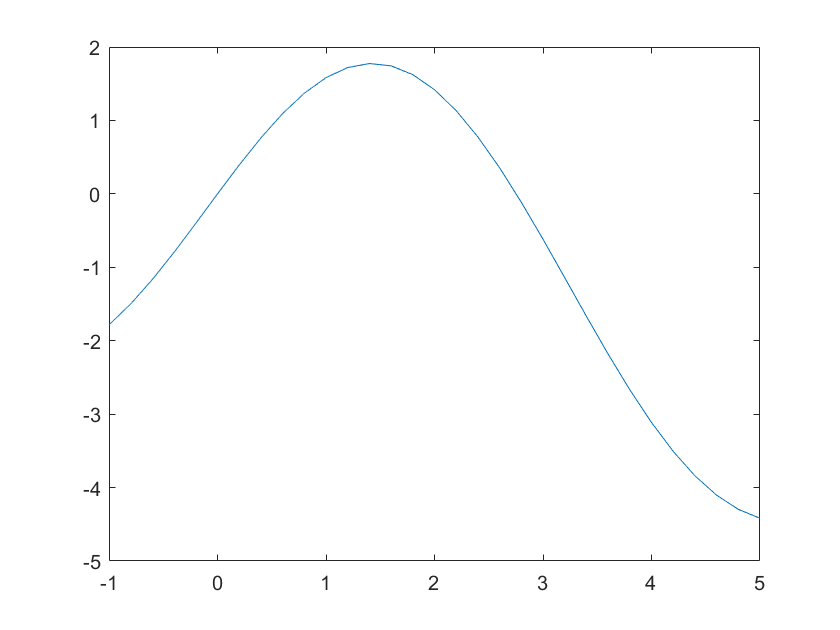

plot(-1:0.2:5,function_x(-1:0.2:5))

x_lower = 0;
x_upper = 4;

x_root_previous  = 0;
error_approximation = 100;
fprintf('')
i = 1;

while error_approximation > 1
    
    approximationValue_lower = (x_lower) * 0.618;
    approximationValue_upper = (x_upper) * 0.618;
    
    function_x(approximationValue_lower);
    function_x(approximationValue_upper);
    
    x_root = (x_lower * approximationValue_upper - x_upper * approximationValue_lower)/( ...
        approximationVal
    
    approximationValue_root = function_x(x_root);
    
    if approximationValue_root < 0
        x_upper = x_root;
    elseif approximationValue_root > 0
        x_lower = x_root;
    end
    
    error_approximation = abs(epsilon_a(x_root_previous,x_root));
    
    mark2 = plot(x_root,approximationValue_root,'o', 'MarkerFaceColor', 'r','MarkerEdgeColor','none');
    
    fprintf('Iteration : %i \t\t Estimated root : %0.4f \t\t Approximate Relative Error : %0.4f \n', ...
        i,x_root,error_approximation);
    
    i = i + 1;
    x_root_previous = x_root;
end

Unrecognized function or variable 'epsilon_a'.